clc
close all
clear all
cla
fprintf(' Data loading...\n');

 Data loading...


% load gt
rootfolder = '../../exp/'

rootfolder = '../../exp/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

currentfolder = 'tartanair_toy_exp_50_0.5/'

index = 3

index =      3


index_s = int2str(index)

index_s = '3'

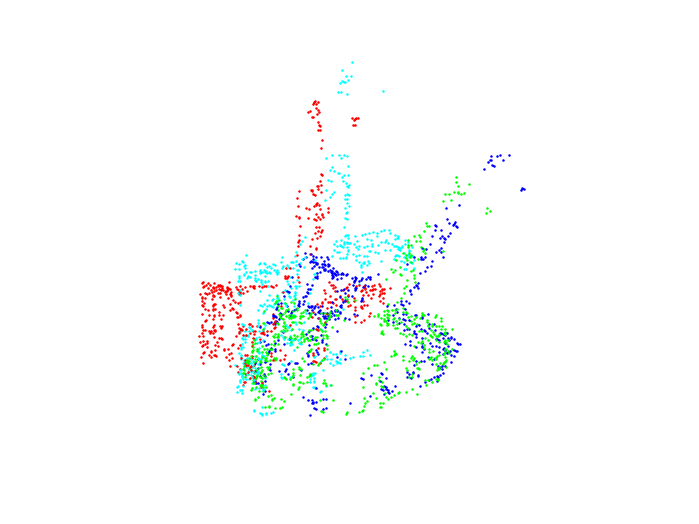

V1 = pcread(append(rootfolder,currentfolder,index_s,'/0normal.pcd'))';
V2 = pcread(append(rootfolder,currentfolder,index_s,'/1normal.pcd'))';
V3 = pcread(append(rootfolder,currentfolder,index_s,'/2normal.pcd'))';
V4 = pcread(append(rootfolder,currentfolder,index_s,'/3normal.pcd'))';
V = {V1,V2,V3,V4}';
figure(1)
colormap = {[255,0,0],[0,255,0],[0,0,255],[0,255,255]};

figure(2) 
hold on
for i=1:4
    pointscolor=uint8(zeros(V{i}.Count,3));
    pointscolor(:,1)=colormap{i}(1);
    pointscolor(:,2)=colormap{i}(2);
    pointscolor(:,3)=colormap{i}(3);
    V{i}.Color=pointscolor;
    pcshow(V{i});
    set(gcf, 'color','w')
    view([1.8 24.5])
end
hold off

## Read cvo pose and do transformation

cla
gtfilename = append(rootfolder,currentfolder,index_s,'/rkhs_results.txt')

gtfilename = '../../exp/tartanair_toy_exp_50_0.5/3/rkhs_results.txt'

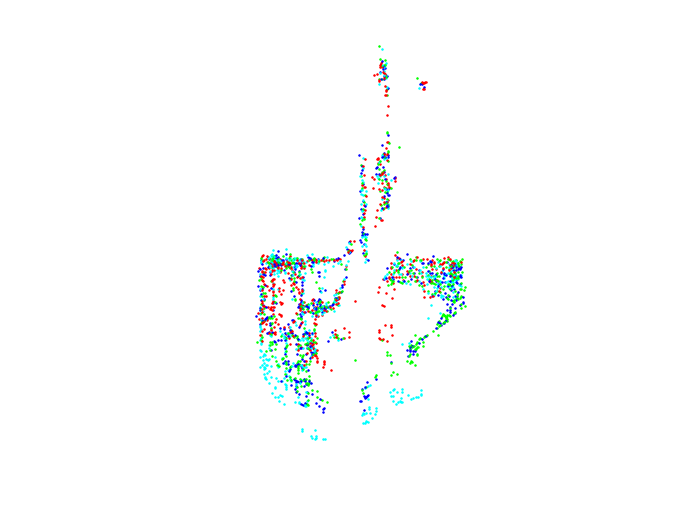

A = readmatrix(gtfilename);
Tcvo = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
figure(3)
hold on
for i=1:4
    T = Tcvo{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    ptCloudOut = V{i};
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = V{i}.Color;
    pcshow(ptCloudOut);
    view([1.8 24.5])
    set(gcf, 'color','w')
end
hold off

## Read jrmpc pose and do transformation

cla
gtfilename = append(rootfolder,currentfolder,index_s,'/jrmpc.txt')

gtfilename = '../../exp/tartanair_toy_exp_50_0.5/3/jrmpc.txt'

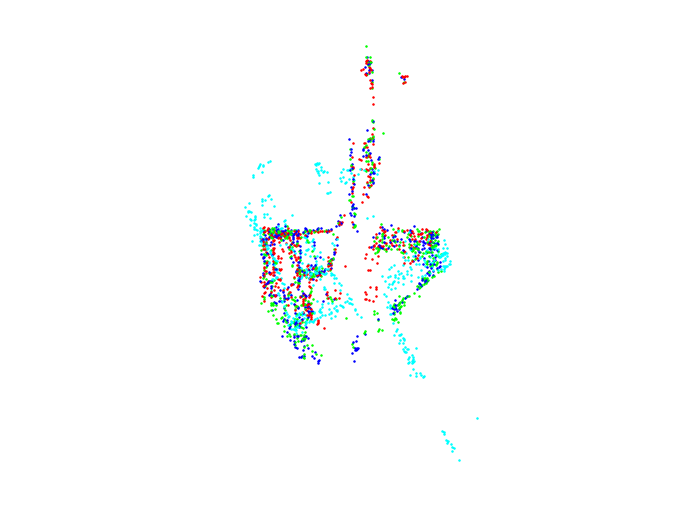

A = readmatrix(gtfilename);
Tres = {reshape(A(1,:),[4,4])',reshape(A(2,:),[4,4])',reshape(A(3,:),[4,4])',reshape(A(4,:),[4,4])'}';
Tfixed_res = {};
for j=1:4
    Tfixed_res{j}= inv(Tres{1})*Tres{j};
end
figure(4)
hold on
for i=1:4
    T = Tfixed_res{i};
    transform_p = bsxfun(@plus,T(1:3,1:3) *V{i}.Location',T(1:3,4))';
    ptCloudOut = V{i};
    ptCloudOut = pointCloud(transform_p);
    ptCloudOut.Color = V{i}.Color;
    pcshow(ptCloudOut);
    view([1.8 24.5])
    set(gcf, 'color','w')
end
hold off